clear all, close all, clc

## Prob-2.5

Given the follows-

mu_p = 4.04e-3;           % mean
sg_p = 3.213e-3;          % StD
sg2 = sg_p^2;             % variance

Let's find the values for mean and std

% type root2d.m

fun = @root2d;
x0 = [1e-3, 1e-3];      % initialize near 0, not @ 0

x = fsolve(fun, x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


So, we have value of $\alpha$ and $\beta \;$

alf = x(1)

alf = 0.7003

bet = x(2)

bet = 0.0032

% sg = al; mu = bt;

The utility of above parameters are for following equation-


$$p{\left(z\right)}=\frac{1}{\sqrt{2\pi }\alpha z}\exp {\left[-{{\left(\frac{\ln \frac{z}{\beta }}{\sqrt{2}\alpha }\right)}}^2 \right]}$$


Where, $m=\beta e^{\frac{\alpha^2 }{2}}$     and $\sigma^2 =\beta^2 e^{\alpha^2 } \left(e^{\alpha^2 } -1\right)$

But MATLAB apparently use different parameters to calculate lognormal pdf. So, we need to find some altered value for $\mu \;$ and $\sigma \;$-  

$\mu =\ln \frac{\mu_p^2 }{\sqrt{\mu_p^2 +\sigma_p^2 }}$;     $\sigma =\sqrt{\ln {\left(\frac{\sigma_p^2 }{\mu_p^2 }+1\right)}}$

  dnm = sqrt(mu_p^2 + sg_p^2);      % denominator
mu = log( mu_p^2 /dnm)

mu = -5.7566


sg = sqrt( log(sg_p^2 /mu_p^2 + 1))

sg = 0.7001

Now, let's find the lognormal probability distribution-

N = 1e4;
lm_mx = 1e-1;           % max value of fail-rate
lm_mn = 1e-4;           % min value of fail-rate
% lm2 = logspace(-4, -1, N+1);
lm = linspace(lm_mn, lm_mx, N+1);
% dlm = lm(2) - lm(1);
dlm = (lm_mx - lm_mn)/N

dlm = 9.9900e-06

Now, let's find the log normal distribution. The

P_lm = lognpdf(lm,mu,sg);       % lognormal PDF

Now, let's find the probability of B, when $\lambda$ is given, 


$$P{\left(B,\lambda_i \right)}={\left(\begin{array}{c}
D\\
F
\end{array}\right)}\lambda_i^F {{\left(1-\lambda_i \right)}}^{D-F}$$


D = 250;            % demand
F = 10;             % failure
    C = nchoosek(D,F);

P_B_lm = C .*lm.^F .*(1 - lm).^(D-F);

Now, find the trotal probability for each group-


$$P{{\left(B\right)}}_i =P{\left(B|\lambda_i \right)}P{\left(\lambda_i \right)}d\lambda_i$$


P_B = P_B_lm .*P_lm *dlm;

Then, find the probability of $\lambda \;$, given B


$${\left(\lambda_i ,B\right)}=\frac{\left.P{\left(\lambda_i \right)}P\left(B\right|\lambda_i \right)}{\sum P{{\left(B\right)}}_i }$$


    sum_P_B = sum(P_B); 
P_lm_B = P_lm .*P_B_lm ./sum_P_B;

Now, let's plot everyting-

#### Plot

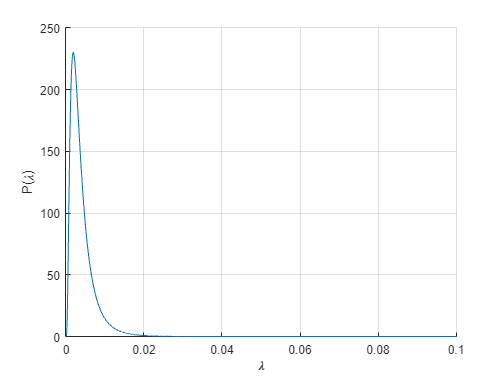

figure(1)
grid on, hold on
semilogx(lm, P_lm)
xlabel('\lambda')
ylabel('P(\lambda)')

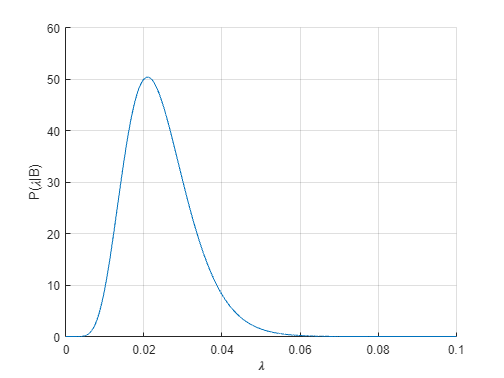


figure(2)
grid on, hold on
semilogx(lm, P_lm_B)
xlabel('\lambda')
ylabel('P(\lambda|B)')

Now, let's measure the posterior mean and variance


$$\mu_s =\sum_i^N \mu_i$$


mu_s_i = lm .*P_lm_B *dlm;
mu_s = sum(mu_s_i)

mu_s = 0.0242

(Ans)


$$\sigma_s =\sqrt{\sum_i^N \sigma_i^2 -\mu_s^2 }$$


vr_s_i = lm.^2 .*P_lm_B *dlm;
sg_s = sqrt( sum(vr_s_i) - mu_s^2 )

sg_s = 0.0085

(Ans)

###############################

## Functions

function F = root2d(x)
m = 4.04e-3;            % mean
sg = 3.213e-3;          % STD
sg2 = sg^2;             % variance

Now, from Gamma dist. we know the following-

$m=\beta e^{\frac{\alpha^2 }{2}}$; and


$$\sigma {\;}^2 =\beta^2 e^{\alpha^2 } \left(e^{\alpha^2 } -1\right)$$


Let's build the system of equations. See [here](https://www.mathworks.com/help/optim/ug/fsolve.html#d126e113417) for example

F(1) = m - x(2) *exp( x(1)^2 /2);
F(2) = sg2 - x(2)^2 *exp(x(1)^2) *( exp(x(1)^2) - 1);
end 
